%Inputs
clc
clear
%Inputs
clc
clear

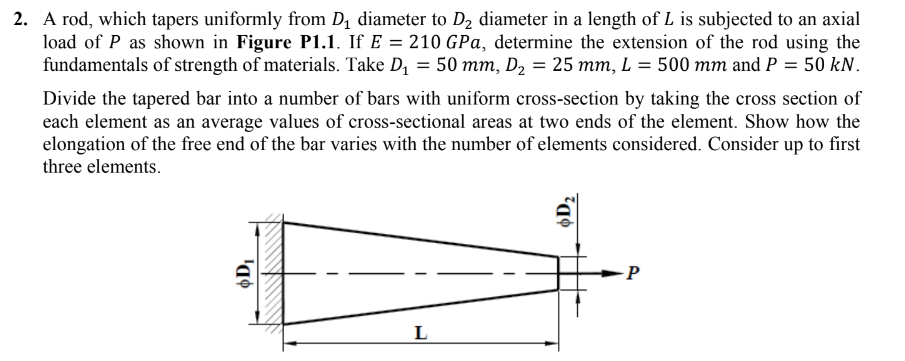

format shortE
L=0.5

L =    5.0000e-01


D1=0.05

D1 =    5.0000e-02


D2=0.025

D2 =    2.5000e-02


P=50000

P =        50000


E=210e9

E =    2.1000e+11


Exact Value Calculation:

ev= 4*P*L/(pi()*E*D1*D2)

ev =    1.2126e-04


Input the number of elements for finding the deflection using FEM

n=input("Enter the number of elements: ")

n =      2


Loop for finding the value of x,D and A required for each element

for m=1:1+n
    x(m)=(m-1)*L/n
    D(m)=D1-(D1-D2)*x(m)/L
    A(m)=pi()*(D(m)^2)/4
end

x =      0


D =    5.0000e-02


A =    1.9635e-03


x =             0   2.5000e-01


D =    5.0000e-02   3.7500e-02


A =    1.9635e-03   1.1045e-03


x =             0   2.5000e-01   5.0000e-01


D =    5.0000e-02   3.7500e-02   2.5000e-02


A =    1.9635e-03   1.1045e-03   4.9087e-04


Area average

for i=1:n
    Aa(i)=(A(i)+A(i+1))/2
end

Aa =    1.5340e-03


Aa =    1.5340e-03   7.9767e-04


Taking initial deformation =0 and taking average of area at two ends for area of the element, we have,

td(m)=0;
for m=1:n
    td(m)=P*(L/n)/(E*Aa(m))
end 

td =    3.8803e-05            0            0


td =    3.8803e-05   7.4622e-05            0


total=sum(td)

total =    1.1343e-04


Calculation of error percentage

error_percentage=abs(total-ev)*100/ev

error_percentage =    6.4615e+00


fprintf("The total deformation is %.15f ",td);

The total deformation is 0.000038803490887 The total deformation is 0.000074622097860 The total deformation is 0.000000000000000 

fprintf("The percentage error is %f",error_percentage);

The percentage error is 6.461538

disp(error_percentage);

   6.4615e+00

